# **Proof of Concept**

**Notes: **It needs Yalmip and OSQP. Yalmip should install himself automatically both on Windows and Linux. OSQP should automatically install on Linux, if there are any problems read the README. On Windows you need to install OSQP yourself.

There are TONs of other parameters and configuration you can tune and adapt, but atm you need to search them yourself.

clc;
clear variables;

## **Initialization**

%% INIT

% Instantiate main Class:
hpc = hpc_lab;

Size: 6552 bytes


chip1 = hpc_chiplet;

[Therm] The system is Observable!
[Therm] Observability Gramian det: 1.7217e-66


% Rows and Columns
chip1.Nv = 3;

[TM] Remember to change Nh, epos, and the floorplan accordingly


chip1.Nh = 5;

[TM] Remember to change Nv, epos, and the floorplan accordingly



% Core number
chip1.Nc = chip1.Nv*chip1.Nh; %20

[TM] Remember to change Nh, Nv, epos, the parameter deviation vector, and the floorplan accordingly



% Number of Voltage Domains
chip1.vd = 4; %chip1.Nc;

% How the cores are distributed per domain
%chip1.VDom = ... ;
% Alternatively
%TODO: not working, need to fix!
chip1.VDom = hpc.default_VDom_config(chip1.Nh, chip1.Nv, chip1.vd);

% Default Floorplan and Parameter deviation vector
chip1.default_floorplan_config();
chip1.create_model_deviation();

%Decide simulation frequency (discrete timing)
chip1.Ts = 5e-5;

%Decide total simulation time
hpc.tsim = 2;

%Presence/Absence of sensor noise:
chip1.sensor_noise = 1;
chip1.sensors_active = [0 0 0 1];

%Thermal model version
chip1.model_ver = 0;

#### After the configuration of the Thermal Model, run the model creation & others

chip1.model_init();

[Therm] The system is Observable!
[Therm] Observability Gramian det: 1.7405e-80


chip1.create_core_pw_noise();

#### Choose targets

% Initial Temperature condition
hpc.t_init{1} = (hpc.temp_amb+10)*ones(chip1.Ns,1);

%Input maximum frequency
hpc.Ts_target;

tt = min(ceil(hpc.tsim / hpc.Ts_target)+1, (hpc.tsim/1e-4+1));

% Target Frequency Trajectory
hpc.frtrc{1} = 3.45 * ones(tt, chip1.Nc);

%Target Power Budget
hpc.chip_pw_budget{1} = 450/36*chip1.Nc*ones(tt,1);

hpc.toto_pw_budget = hpc.chip_pw_budget{1} * 1.5;

tu = ceil(tt/4);
hpc.chip_pw_budget{1}(tu+1:2*tu) = 2*chip1.Nc;
hpc.chip_pw_budget{1}(2*tu+1:3*tu) = 5*chip1.Nc;
hpc.chip_pw_budget{1}(3*tu+1:3*tu+ceil(tu/2)) = 3*chip1.Nc;
hpc.chip_pw_budget{1}(3*tu+ceil(tu/2)+1:end) = 8*chip1.Nc;
5

ans = 5

hpc.quad_pw_budget{1} = 450/36*chip1.Nc*ones(2,chip1.vd);

%Others, TODO
%hpc.min_pw_red = 0.6;

#### After all the configurations are done, running the checks:

chip1.anteSimCheckTM();
hpc.anteSimCheckLab(chip1);
chip1.anteSimCheckPM();

## Run Autonomous thermal simulation

% Total time of simulation (s)
tsim_aut = 10;

% Changing Ts to improve the speed of simulation
%{
hpc.Ts = 250e-6;
chip1.model_init();
hpc.sim_tm_autonomous(tsim_aut)
hpc.Ts = 5e-5;
chip1.model_init();
%}

### **Generate Workload trace:**

%Probability of each workload type [idle, int, float, mem, vec]
chip1.wl_prob = [0.01 0.01 0.01 0.5 0.5]; %[0.0345 0.3448 0.3448 0.2414 0.0345];

%Minimum execution time (us) of each workload type
chip1.wl_min_exec_us = [510 100 100 480 520];	

%Mean execution time (us) of each workload type
chip1.wl_mean_exec_us = [120e2 210e1 180e1 560e2 1.2e6/1e1];

%Generate it
hpc.wltrc{1} = chip1.generate_wl_trace(chip1.Nc, hpc.tsim, chip1.F_max, 0);


## **Controllers**

addpath('Controllers/');

## **Fuzzy Controller**

ctrl = Fuzzy(chip1);
ctrl.C = chip1.C(1:ctrl.lNc,:);
ctrl.T_target = ones(ctrl.lNc, 1)*chip1.core_limit_temp;

%Controller frequency (s)
ctrl.Ts_ctrl = 5e-4;

ctrl.Tsensor_amplitude = chip1.sensor_noise*chip1.sensor_noise_amplitude(chip1.PVT_T);
ctrl.Fdiscretization_step = chip1.F_discretization_step;


%Launch Simulation
CM = [1];
ctrl.comm_mat = 1;
ctrl.multi_der_fcn = @mff;
ctrl.multi_learn_rate = 0.1;
tic;
hpc.simulation(ctrl,chip1, CM, 1);
toc;

## **SotA / CP MPC**

ctrl = cp_mpc(chip1);
ctrl.C = eye(chip1.Ns);
ctrl.Fdiscretization_step = chip1.F_discretization_step;

ctrl.save_solver_stats = 0;

%Controller frequency (s)
ctrl.Ts_ctrl = 1e-3;
%ctrl.Nhzn = 20;

%Robust Margins for T and P
ctrl.Cty = zeros(ctrl.Nhzn, chip1.Nc);
ctrl.Ctu = zeros(ctrl.Nhzn, chip1.Nc);

%Reference Tracking Objective Matrix
R_coeff = 10;
ctrl.Rt = R_coeff*eye(chip1.Nc);

%Others
ctrl.Rs = zeros(chip1.Nc);
ctrl.R = zeros(chip1.Nc);
ctrl.Q = zeros(chip1.Ns);

Optimizer object with 114 inputs (4 blocks) and 112 outputs (2 blocks). Solver: OSQP


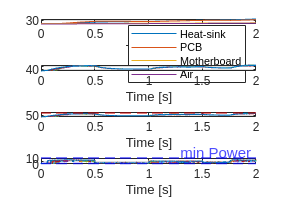

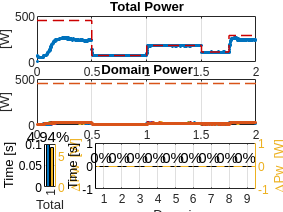

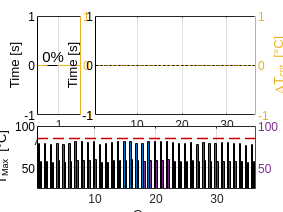

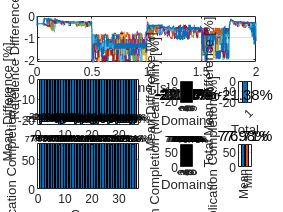

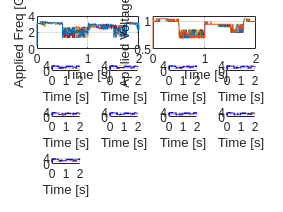

[CTRL][MPC] number of times the optimization algorithm failed:0/2000


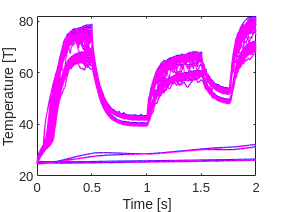

%Launch Simulation
CM = [1];
tic;
simres = hpc.simulation(ctrl,chip1,CM,1);

for i=1:length(simres)
    res(i) = hpc.stats_analysis(ctrl,chip1, simres(i), i);
end
toc;

Elapsed time is 55.346194 seconds.


## **My-current-research MPC**

ctrl = black_wolf(chip1);
ctrl.C = chip1.C; %eye(hpc.Ns);
ctrl.Fdiscretization_step = chip1.F_discretization_step;
ctrl.lwl_mem = chip1.wl_mem_weigth;

ctrl.Tmpc_off = -370;

ctrl.Gw = eye(chip1.Ns);
Qc = 3.4e-4; %0.1;
ctrl.Qcov = Qc*eye(chip1.Ns);
Rc = 0.33; %1;
ctrl.Rcov = Rc*eye(size(ctrl.C,1)); 

%Controller frequency (s)
ctrl.Ts_ctrl = 5e-3;
%ctrl.Nhzn = 20;

%Robust Margins for T and P
ctrl.Cty = zeros(ctrl.Nhzn, chip1.Nc);
ctrl.Ctu = zeros(ctrl.Nhzn, chip1.Nc);

%Reference Tracking Objective Matrix
R_coeff = 20; %absolute value
R_shared = 7;%15; % R_coeff/0.2;
R_track = 20;
Q_coeff = 0.5; %6 %1e-2%2.5; 

% Create matrixes
ctrl.R = R_coeff*eye(chip1.Nc);
ctrl.Rt = R_track*eye(chip1.Nc);
ctrl.Rs = zeros(chip1.Nc);
for v=1:chip1.vd
	%Here I could create an accumulation thing that need to be
	%optimized (e.g. reduced) that contains the deltaF among quadrant 
	ctrl.Rs = ctrl.Rs + chip1.VDom(:,v)*chip1.VDom(:,v)' / sum(chip1.VDom(:,v))^2 * R_shared;
end
%TODO: Assuming that the diagonal is full
ctrl.Rs(~eye(size(ctrl.Rs))) = ctrl.Rs(~eye(size(ctrl.Rs))) * (-1);
cores_per_dom = sum(chip1.VDom);
ctrl.Rs(logical(eye(size(ctrl.Rs)))) = ctrl.Rs(~~eye(size(ctrl.Rs))) .* chip1.VDom*cores_per_dom'; %here I need ~~ to converto to logical values

ctrl.Q = (Q_coeff)*eye(chip1.Ns);

%{
Ew = R_coeff;
bm = Ew/2*eye(hpc.Nc);
bM = [zeros(hpc.Nc) bm; 
       bm zeros(hpc.Nc)];
ctrl.RE = [bM zeros(size(bM));
            zeros(size(bM)) bM];
%}


%Launch Simulation
CM = [1];
tic;
simres = hpc.simulation(ctrl,chip1,CM,1);
toc;

# **Parallelization**

chip2 = hpc_chiplet;

% differentiate it a bit:
% Rows and Columns
chip2.Nv = 3;
chip2.Nh = 3;

% Core number
chip2.Nc = chip2.Nv*chip2.Nh; %20

% Number of Voltage Domains
chip2.vd = 2; %chip1.Nc;

% How the cores are distributed per domain
%chip1.VDom = ... ;
% Alternatively
%TODO: not working, need to fix!
chip2.VDom = hpc.default_VDom_config(chip2.Nh, chip2.Nv, chip2.vd);

% Default Floorplan and Parameter deviation vector
chip2.default_floorplan_config();
chip2.create_model_deviation();

chip2.model_init();
chip2.create_core_pw_noise();

#### First Attempt at separating them

% Initial Temperature condition
hpc.t_init{2} = (hpc.temp_amb+10)*ones(chip2.Ns,1);

%Input maximum frequency
hpc.Ts_target;

tt = min(ceil(hpc.tsim / hpc.Ts_target)+1, (hpc.tsim/1e-4+1));

% Target Frequency Trajectory
hpc.frtrc{2} = 3.45 * ones(tt, chip2.Nc);

%Target Power Budget
hpc.chip_pw_budget{2} = 450/36*chip1.Nc*ones(tt,1);

tu = ceil(tt/4);
hpc.chip_pw_budget{2}(tu+1:2*tu) = 2*chip1.Nc;
hpc.chip_pw_budget{2}(2*tu+1:3*tu) = 5*chip1.Nc;
hpc.chip_pw_budget{2}(3*tu+1:3*tu+ceil(tu/2)) = 3*chip1.Nc;
hpc.chip_pw_budget{2}(3*tu+ceil(tu/2)+1:end) = 8*chip1.Nc;
5
hpc.quad_pw_budget{2} = 450/36*chip2.Nc*ones(2,chip2.vd);

%Others, TODO
%hpc.min_pw_red = 0.6;

#### After all the configurations are done, running the checks:

chip2.anteSimCheckTM();
hpc.anteSimCheckLab(chip2);
chip2.anteSimCheckPM();

%Probability of each workload type [idle, int, float, mem, vec]
chip2.wl_prob = [0.01 0.01 0.01 0.5 0.5]; %[0.0345 0.3448 0.3448 0.2414 0.0345];

%Minimum execution time (us) of each workload type
chip2.wl_min_exec_us = [510 100 100 480 520];	

%Mean execution time (us) of each workload type
chip2.wl_mean_exec_us = [120e2 210e1 180e1 560e2 1.2e6/1e1];

%Generate it
hpc.wltrc{2} = chip2.generate_wl_trace(chip2.Nc, hpc.tsim, chip1.F_max, 0);


#### Chiplet 1 controller 1

ctrl1 = Fuzzy(chip1);
ctrl1.C = chip1.C(1:ctrl1.lNc,:);
ctrl1.T_target = ones(ctrl1.lNc, 1)*chip1.core_limit_temp;

%Controller frequency (s)
ctrl1.Ts_ctrl = 5e-4;

ctrl1.Tsensor_amplitude = chip1.sensor_noise*chip1.sensor_noise_amplitude(chip1.PVT_T);
ctrl1.Fdiscretization_step = chip1.F_discretization_step;


#### Chiplet 2 controller 2

ctrl2 = Fuzzy(chip2);
ctrl2.C = chip2.C(1:ctrl2.lNc,:);
ctrl2.T_target = ones(ctrl2.lNc, 1)*chip2.core_limit_temp;

%Controller frequency (s)
ctrl2.Ts_ctrl = 5e-4;

ctrl2.Tsensor_amplitude = chip2.sensor_noise*chip2.sensor_noise_amplitude(chip2.PVT_T);
ctrl2.Fdiscretization_step = chip2.F_discretization_step;


### Launch Simulation

%Launch Simulation
ctrlar = [ctrl1, ctrl2];
chipar = [chip1, chip2];
CM = [0,1;1,0];

ctrl1.comm_mat = CM;
ctrl1.multi_der_fcn = @mff;
ctrl1.multi_learn_rate = 0.1;
ctrl2.comm_mat = CM;
ctrl2.multi_der_fcn = @mff;
ctrl2.multi_learn_rate = 0.1;

tic;
simres = hpc.simulation(ctrlar,chipar, CM, 1);
toc;

for i=1:length(simres)
    res(i) = hpc.stats_analysis(ctrlar(i),chipar(i), simres(i), i);
end

%{
ctrl = HLC;
ctrl.C = eye(hpc.Ns);

%Controller frequency (s)
ctrl.Ts_ctrl = hpc.Ts; %50e-3;
ctrl.hp = 5e-4;



%Launch Simulation
tic;
%hpc.simulation(ctrl,1);
toc;
%}


%{
wlpl = 1;

hpc.wltrc = zeros(hpc.Nc, hpc.ipl, length(hpc.wltrc));
hpc.wltrc(:,wlpl,:) = 1;

ctrl = dumb_test;
ctrl.C = eye(hpc.Ns);

ctrl.freq = 0.4;
%Launch Simulation
tic;
%hpc.simulation(ctrl,1);
toc;

ctrl.freq = 3.4;
%Launch Simulation
tic;
%hpc.simulation(ctrl,1);
toc;
%}



function [x] = mff(v1,id)
    x = 0;
end